clear all;
close all;
clc;

original_image_path = 'D:\Studying\RetinaNet_Project\all_DICOM_files\AllDICOMs\22579730_bbd6a3a35438c11b_MG_R_ML_ANON.dcm'

original_image_path = 'D:\Studying\RetinaNet_Project\all_DICOM_files\AllDICOMs\22579730_bbd6a3a35438c11b_MG_R_ML_ANON.dcm'

image_patch_path = 'D:\Studying\RetinaNet_project_image_patches\with_mass\22579730\temp_dicom_22579730_crop_0.tif'

image_patch_path = 'D:\Studying\RetinaNet_project_image_patches\with_mass\22579730\temp_dicom_22579730_crop_0.tif'


dicom_image = dicomread(original_image_path)

dicom_image = 3328×2560 uint16 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

image_patch = imread(image_patch_path)

image_patch = 1024×1024 uint16 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  



subplot(1,2,1)
mass_bbox_original = [1647, 939, 2061, 1371]

mass_bbox_original =         1647         939        2061        1371


imshow(dicom_image, []);
rectangle('Position', [mass_bbox_original(1), mass_bbox_original(2), mass_bbox_original(3) - mass_bbox_original(1), ...
    mass_bbox_original(4) - mass_bbox_original(2)], "EdgeColor", 'r', "LineWidth", 1.3)


subplot(1,2,2)
mass_bbox_patch = [121, 162, 536, 594]

mass_bbox_patch =    121   162   536   594


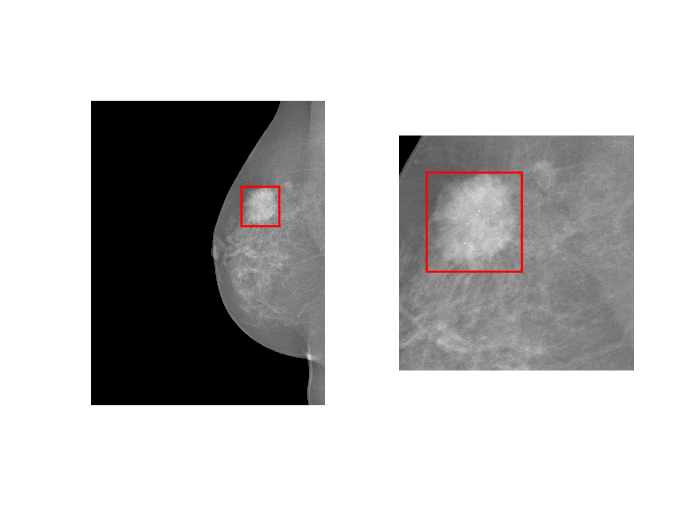

imshow(image_patch, []);
rectangle('Position', [mass_bbox_patch(1), mass_bbox_patch(2), mass_bbox_patch(3) - mass_bbox_patch(1), ...
    mass_bbox_patch(4) - mass_bbox_patch(2)], "EdgeColor", 'r', "LineWidth", 1.3)